Demo code for Figure 6 of Idesis (2022) - Introducing structural disconnection masks in whole-brain models. A mechanistic explanation of stroke patients effective connectivity

Adapted by: Sebastian Idesis - sebastian.idesis@upf.edu (Feb 2022)

Initialize script

clear all;close all;clc; %Close everything

Add helper functions and data to path

addpath('Functions');
addpath('Data');

Load Time series, Structural connectivity and effective connectivity

load Data_Hopf_model.mat %Demo data (Only 2 subjects per group)
sc_control=SC_control;

Calculate disconnection types per area interaction


%ii < 200 and jj < 200 = cort-cort
%ii > 200 and jj > 200 = sub-sub
%ii < 200 and jj > 200 = cort-sub
%ii > 200 and jj < 200 = sub-cort

total_discon_amount_CC = zeros(1,size(Mask_patients,3));total_discon_amount_SS = zeros(1,size(Mask_patients,3));
total_discon_amount_CS = zeros(1,size(Mask_patients,3));total_discon_amount_SC = zeros(1,size(Mask_patients,3));

total_discon_amount_all_quadrants = zeros(1,size(Mask_patients,3));

combined_discon_sum_CC = zeros(1,size(Mask_patients,3));combined_discon_sum_SS = zeros(1,size(Mask_patients,3));
combined_discon_sum_CS = zeros(1,size(Mask_patients,3));combined_discon_sum_SC = zeros(1,size(Mask_patients,3));

partial_discon_amount_CC = zeros(1,size(Mask_patients,3)); partial_discon_amount_SS = zeros(1,size(Mask_patients,3));
partial_discon_amount_CS = zeros(1,size(Mask_patients,3)); partial_discon_amount_SC = zeros(1,size(Mask_patients,3));

partial_discon_sum_CC = zeros(1,size(Mask_patients,3));partial_discon_sum_SS = zeros(1,size(Mask_patients,3));
partial_discon_sum_CS = zeros(1,size(Mask_patients,3));partial_discon_sum_SC = zeros(1,size(Mask_patients,3));




for subj = 1:size(Mask_patients,3)
    mask=Mask_patients(:,:,subj);
    condition_1 = 0;condition_2 = 0;condition_3 = 0;condition_4 = 0;
   for ii = 1:size(Mask_patients,1)
       for jj = 1:size(Mask_patients,1)
           if ii <= 200 && jj <= 200 
               condition = 'cort-cort'; condition_1 = condition_1 +1;
               if sc_control(ii,jj)>0 && mask(ii,jj)==0
                   total_discon_amount_CC(subj) = total_discon_amount_CC(subj) + 1;
                   combined_discon_sum_CC(subj) = combined_discon_sum_CC(subj) + 100;
                   total_discon_amount_all_quadrants(subj) = total_discon_amount_all_quadrants(subj) + 1;
               elseif sc_control(ii,jj)>0 && mask(ii,jj)> 0 && mask(ii,jj)< 100
                   partial_discon_amount_CC(subj) = partial_discon_amount_CC(subj) +1;
                   partial_discon_sum_CC(subj) = partial_discon_sum_CC(subj) + (100-mask(ii,jj));
                   combined_discon_sum_CC(subj) = combined_discon_sum_CC(subj) + (100-mask(ii,jj));
               end
           elseif ii > 200 && jj > 200
               condition = 'sub-sub'; condition_2 = condition_2 +1;
               if sc_control(ii,jj)>0 && mask(ii,jj)==0
                   total_discon_amount_SS(subj) = total_discon_amount_SS(subj) + 1;
                   combined_discon_sum_SS(subj) = combined_discon_sum_SS(subj) + 100;
                   total_discon_amount_all_quadrants(subj) = total_discon_amount_all_quadrants(subj) + 1;
               elseif sc_control(ii,jj)>0 && mask(ii,jj)> 0 && mask(ii,jj)< 100
                   partial_discon_amount_SS(subj) = partial_discon_amount_SS(subj) +1;
                   partial_discon_sum_SS(subj) = partial_discon_sum_SS(subj) +(100-mask(ii,jj));
                   combined_discon_sum_SS(subj) = combined_discon_sum_SS(subj) + (100-mask(ii,jj));
               end
           elseif ii <= 200 && jj > 200
               condition = 'cort-sub'; condition_3 = condition_3 +1;
               if sc_control(ii,jj)>0 && mask(ii,jj)==0
                   total_discon_amount_CS(subj) = total_discon_amount_CS(subj) + 1;
                   combined_discon_sum_CS(subj) = combined_discon_sum_CS(subj) + 100;
                   total_discon_amount_all_quadrants(subj) = total_discon_amount_all_quadrants(subj) + 1;
               elseif sc_control(ii,jj)>0 && mask(ii,jj)> 0 && mask(ii,jj)< 100
                   partial_discon_amount_CS(subj) = partial_discon_amount_CS(subj) +1;
                   partial_discon_sum_CS(subj) = partial_discon_sum_CS(subj) + (100-mask(ii,jj));
                   combined_discon_sum_CS(subj) = combined_discon_sum_CS(subj) + (100-mask(ii,jj));
               end
           elseif ii > 200 && jj <= 200
               condition = 'sub-cort'; condition_4 = condition_4 +1;
               if sc_control(ii,jj)>0 && mask(ii,jj)==0
                   total_discon_amount_SC(subj) = total_discon_amount_SC(subj) + 1;
                   combined_discon_sum_SC(subj) = combined_discon_sum_SC(subj) + 100;
                   total_discon_amount_all_quadrants(subj) = total_discon_amount_all_quadrants(subj) + 1;
               elseif sc_control(ii,jj)>0 && mask(ii,jj)> 0 && mask(ii,jj)< 100
                   partial_discon_amount_SC(subj) = partial_discon_amount_SC(subj) +1;
                   partial_discon_sum_SC(subj) = partial_discon_sum_SC(subj) +(100-mask(ii,jj));
                   combined_discon_sum_SC(subj) = combined_discon_sum_SC(subj) + (100-mask(ii,jj));
               end
           end
       end
   end
   partial_discon_avg_CC(subj) = partial_discon_sum_CC(subj) / partial_discon_amount_CC(subj);
   partial_discon_avg_CS(subj) = partial_discon_sum_CS(subj) / partial_discon_amount_CS(subj);
   partial_discon_avg_SC(subj) = partial_discon_sum_SC(subj) / partial_discon_amount_SC(subj);
   partial_discon_avg_SS(subj) = partial_discon_sum_SS(subj) / partial_discon_amount_SS(subj);
   
   combined_discon_avg_CC(subj) = combined_discon_sum_CC(subj) / (partial_discon_amount_CC(subj) + total_discon_amount_CC(subj));
   combined_discon_avg_CS(subj) = combined_discon_sum_CS(subj) / (partial_discon_amount_CS(subj) + total_discon_amount_CS(subj));
   combined_discon_avg_SC(subj) = combined_discon_sum_SC(subj) / (partial_discon_amount_SC(subj) + total_discon_amount_SC(subj));
   combined_discon_avg_SS(subj) = combined_discon_sum_SS(subj) / (partial_discon_amount_SS(subj) + total_discon_amount_SS(subj));
   
   relative_amount_discon_CC(subj) = partial_discon_amount_CC(subj)/total_discon_amount_all_quadrants(subj);
   relative_amount_discon_CS(subj) = partial_discon_amount_CS(subj)/total_discon_amount_all_quadrants(subj);
   relative_amount_discon_SC(subj) = partial_discon_amount_SC(subj)/total_discon_amount_all_quadrants(subj);
   relative_amount_discon_SS(subj) = partial_discon_amount_SS(subj)/total_discon_amount_all_quadrants(subj);
end


USE THESE METRICS FOR THE REGRESSION ANALYSIS WANTED

Here it will be a perfect straight line because there is only 2 subjects

Example:

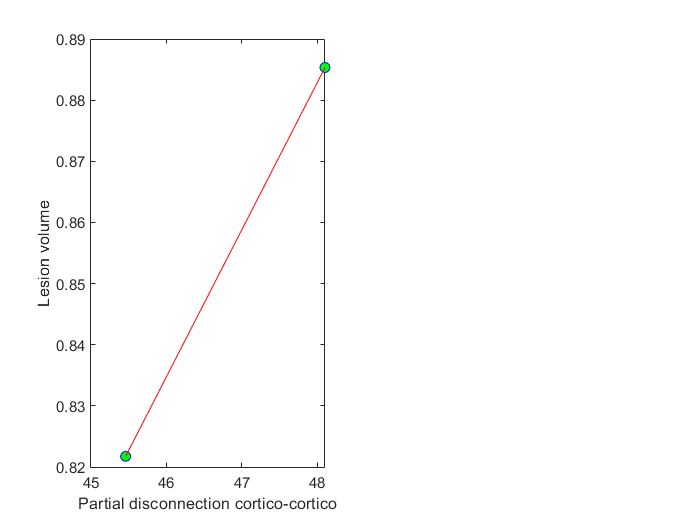

lesion_volume=rand(1,size(EC_patients,3));

figure()
subplot(121)
mdlr = fitlm(partial_discon_avg_CC,lesion_volume);
regr_plot=plot(mdlr);
legend('off')
xlabel('Partial disconnection cortico-cortico');
ylabel('Lesion volume')
set(regr_plot(1),'Marker','o')
set(regr_plot(1),'MarkerFaceColor','g')
title('')